% Solve for the coefficients of the CCM.
% We use monochrome and RGB values from 3 patches on a color chart.
% This gives us 3 matrices each with 3 unknowns and 3 equations to solve
% for all 9 coefficients in the CCM.
% Each equation is of the form Sc=b.
diary colorCorrectionLog
S_grayscaleMatrix = [
    80 80 80;
    112 112 112;
    66 66 66;
    ]

S_grayscaleMatrix =     80    80    80
   112   112   112
    66    66    66


% S_grayscaleMatrix = [
%     80 0 0;
%     0 112 0;
%     0 0 66;
%     ]

b_redMatrix = [166 65 51]';
b_greenMatrix = [41 145 58]';
b_blueMatrix = [56 65 144]';

% c_redMatrix = S_grayscaleMatrix\b_redMatrix
% c_greenMatrix = S_grayscaleMatrix\b_greenMatrix
% c_blueMatrix = S_grayscaleMatrix\b_blueMatrix

%transformImage(c_redMatrix, c_greenMatrix, c_blueMatrix)

% Show augmented matrix in rref. Visual verification if it is singular.
S_grayscaleMatrix(:,4) = b_redMatrix;
R = rref(S_grayscaleMatrix)

R =      1     1     1     0
     0     0     0     1
     0     0     0     0


% To try to formulate a solution that allows each row of the CCM have
% unique components (a11, a12, a13 are unique instead of identical) we
% eliminate using identical scalar value rows (the patch method) that
% correspond to R1 R2 R3 (different R values of each patch.

% New method has 3 different scalar values map to the same R value in each
% row. This is done by setting an R value (R1=50, etc), and then
% caluclating any scalar value with that R value (online calculator) so the 
% G, B values are arbitrary.

% Therefore, we need 3 grayscale matrices to calculate each row of CCM
% coefficients.
%   [ s11 s12 s13 ]   [ a11 ]     [ R1 ]
%   [ s21 s22 s23 ] * [ a12 ]  =  [ R2 ]
%   [ s31 s32 s33 ]   [ a13 ]     [ R3 ]
                    
S_grayscaleMatrix_red = [
    22 68 120;
    37 65 170;
    67 95 130;
    ];

S_grayscaleMatrix_red =     22    68   120
    37    65   170
    67    95   130


S_grayscaleMatrix_green = [
    33 71 112;
    63 79 141;
    122 138 159;
    ];

S_grayscaleMatrix_green =     33    71   112
    63    79   141
   122   138   159


S_grayscaleMatrix_blue = [
    15 94 183;
    20 56 189;
    32 67 111;
    ];

S_grayscaleMatrix_blue =     15    94   183
    20    56   189
    32    67   111



b_redMatrix =   [50 100 200]';

b_redMatrix =     50
   100
   200


b_greenMatrix = [50 100 200]';

b_greenMatrix =     50
   100
   200


b_blueMatrix =  [50 100 200]';

b_blueMatrix =     50
   100
   200



c_redMatrix = S_grayscaleMatrix_red\b_redMatrix

c_redMatrix =     3.5150
   -0.2765
   -0.0711


% c_redMatrix = lsqr(S_grayscaleMatrix, b_redMatrix)
c_greenMatrix = S_grayscaleMatrix_green\b_greenMatrix

c_greenMatrix =     1.7219
   -0.0105
   -0.0543


c_blueMatrix = S_grayscaleMatrix_blue\b_blueMatrix

c_blueMatrix =     7.5602
   -0.3475
   -0.1679


colorCorrectionMatrix =     3.5150   -0.2765   -0.0711
    1.7219   -0.0105   -0.0543
    7.5602   -0.3475   -0.1679


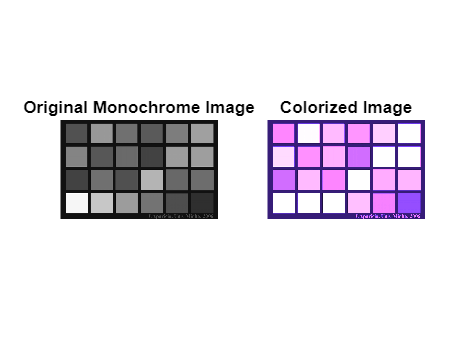

dt = datetime
   09-Jan-2025 17:13:37


filename = "colorized_images/colorized_image_20250109171337.png"

returned_img = 535×850×3 uint8 array
returned_img(:,:,1) =

    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    


returned_img = transformImage(c_redMatrix, c_greenMatrix, c_blueMatrix)

% Test if tinting the image is possible.
% b_redMatrix = [200 + zeros(1, 8)]'
% b_greenMatrix = [50 + zeros(1, 8)]'
% b_blueMatrix = [200 + zeros(1, 8)]'
% 
% c_redMatrix = lsqr(S_grayscaleMatrix, b_redMatrix)
% c_greenMatrix = lsqr(S_grayscaleMatrix, b_greenMatrix)
% c_blueMatrix = lsqr(S_grayscaleMatrix, b_blueMatrix)

% transformImage(c_redMatrix, c_greenMatrix, c_blueMatrix)

function rgbImage = transformImage(c_redMatrix, c_greenMatrix, c_blueMatrix)
% Read the monochrome image.
initial_rgbImage = imread('Reflective-color-chart-reference-COLOR.png', 'png');
grayImage = rgb2gray(initial_rgbImage);

% Define a color correction matrix for RGB color mapping.
% Simple example below.
colorCorrectionMatrix = [
    c_redMatrix'; % Red channel mapping
    c_greenMatrix'; % Green channel mapping
    c_blueMatrix'; % Blue channel mapping
    ]

% Get image dimensions.
[rows, cols] = size(grayImage);

% Initialize RGB image matrix.
% rgbImage = zeros(rows, cols, 3);
rgbImage = initial_rgbImage; % Hijacks format used by imread.

% Apply color correction by looping over each pixel.
for i = 1:rows
    for j = 1:cols
        % Get grayscale value of current pixel.
        grayValue = double(grayImage(i, j)); 

        % Apply color correction matrix to map grayscale value to RGB
        % values.
        rgbValue = colorCorrectionMatrix * [grayValue; grayValue; grayValue];
        
        % Store RBG values in the output image matrix.
        rgbImage(i, j, :) = uint8(rgbValue); % ':' is the rgb vector
    end
end

% Display the original monochrome image and the transformed color image.
figure;
subplot(1, 2, 1);
imshow(grayImage);
title('Original Monochrome Image');
% rgbImage

subplot(1, 2, 2);
imshow(rgbImage);
title('Colorized Image');

% Save the colorized image to a new file.
dt = datetime("now")
dt.Format = 'yyyyMMddHHmmSS';
filename = 'colorized_images/colorized_image_' + string(dt) + '.png'
imwrite(rgbImage, filename);

end
